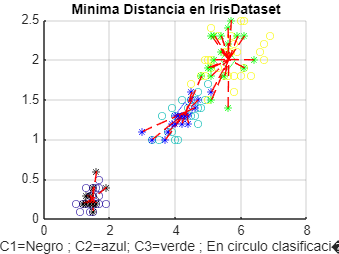

clearvars; close all; clc;

load('iris_dataset');

N =50;  % Cantidad de vectores de caracter�sticas por clase
N_train = 30;  % Seleccionamos cantidad de vectores para entrenamiento

% Asignar numeros de 1 a 3 a las clases
class = ones(1,150);class(1,51:100)=2;class(1,101:end)=3;

% Se usan los primeros N_train para entrenamiento, esto es, estimar la
% media y covarianza para cada clase usando s�lo las caracter�sticas 3 y 4

m1=mean(irisInputs(3:4,1:N_train),2);  % Centroide de la clase C1
m2=mean(irisInputs(3:4,51:51+N_train),2); % Centroide de la clase C2
m3=mean(irisInputs(3:4,101:101+N_train),2); % Centroide de la clase C3 

m=[m1 m2 m3];
S = eye(2);


%% Gr�fica de los puntos de entrenamiento
X1=[irisInputs(3,1:N_train) irisInputs(3,51:51+N_train) irisInputs(3,101:101+N_train)];
X2=[irisInputs(4,1:N_train) irisInputs(4,51:51+N_train) irisInputs(4,101:101+N_train)];
C = [class(1,1:N_train) class(1,51:51+N_train) class(1,101:101+N_train)];

scatter(X1,X2,30,C);

hold on;grid on;
%Grafica de las medias de cada clase
% plot(m1(1),m1(2),'rd', 'MarkerSize',10);
% plot(m2(1),m2(2),'rd','MarkerSize',10);
% plot(m3(1),m3(2),'rd','MarkerSize',10);

plot(m1(1),m1(2),'kd', 'MarkerSize',10);
plot(m2(1),m2(2),'bd','MarkerSize',10);
plot(m3(1),m3(2),'gd','MarkerSize',10);

%% Test

X1_val=[irisInputs(3,N_train+1:50) irisInputs(3,51+N_train:100) irisInputs(3,101+N_train:end)];
X2_val=[irisInputs(4,N_train+1:50) irisInputs(4,51+N_train:100) irisInputs(4,101+N_train:end)];
L_val = (50-N_train);

class_val =zeros(3,L_val*3);
class_val(1,1:L_val)=1;
class_val(2,L_val+1:L_val*2)=1;
class_val(3,2*L_val+1:end)=1;
class_vtrue =zeros(3,L_val*3);

for i=1:L_val*3
    X = [X1_val(i);X2_val(i)];
    
    %Calcula las distancias
    d1=sqrt((X-m1)'*inv(S)*(X-m1)); 
    d2=sqrt((X-m2)'*inv(S)*(X-m2)); 
    d3=sqrt((X-m3)'*inv(S)*(X-m3));
    [d,j1]=max(class_val(:,i));
    [d,j2]=min([d1 d2 d3]);
    class_vtrue(j2,i)=1;

    %Grafica del punto de entrada con un color que depende de la clase
    switch j1
        case (1)
             plot(X(1),X(2),'k*');
        case (2)
             plot(X(1),X(2),'b*');
        otherwise
             plot(X(1),X(2),'g*');
    end
    %Grafica la distancia mas cercana
    line([X(1) m(1,j2)],[X(2) m(2,j2)],'LineStyle','--','Color',[1 0 0]);
end

hold on; xlabel('C1=Negro ; C2=azul; C3=verde ; En circulo clasificaci�n' );
title('Minima Distancia en IrisDataset');

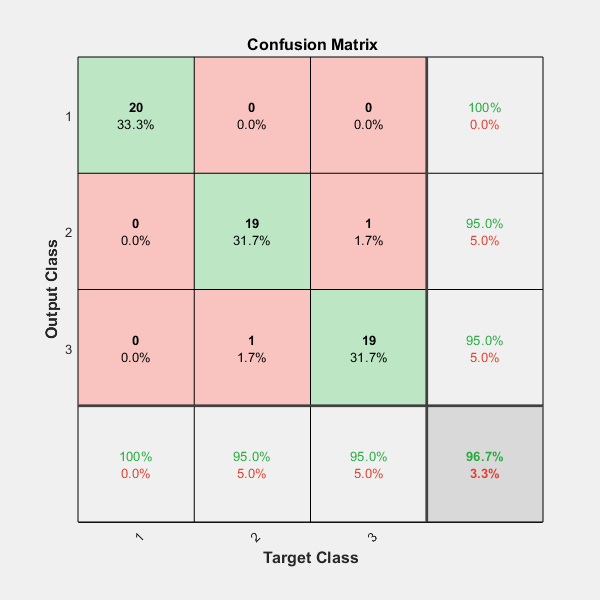

figure;plotconfusion(class_vtrue,class_val);